# Generate Signals in MATLAB

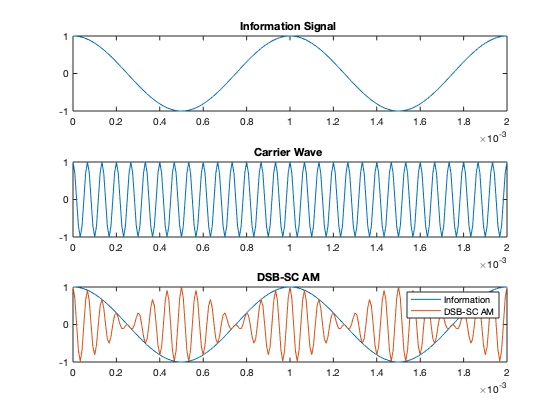

Ai = 1; % information amplitude
fi = 1000; % information frequency
Ac = 1; % carrier amplitude
fc = 15000; % information frequency
fs = 120000; % sampling frequency

% generate time vector
t = [0 : 1/ fs: 0.002 ]; % [ start : step : end ]
% generate sine wave
si = Ai*cos(2*pi*fi*t);
sc = Ac*cos(2*pi*fc*t);
sa = (Ai*Ac/2)*(cos(2*pi*(fc-fi)*t)+cos(2*pi*(fc+fi)*t));
% plot signal
subplot(3,1,1);
plot (t, si);
title ([ 'Information Signal ']);
subplot(3,1,2);
plot (t, sc);
title ([ 'Carrier Wave ']);
subplot(3,1,3);
plot (t, si);
hold on
plot (t, sa);
title ([ 'DSB-SC AM ']);
legend('Information','DSB-SC AM')